# `Md Toufique Hasan`

# `Student Number: 151129267`

# `Exercise date: 13.04.2023`

# `Machine Learning Algorithms: Exercise 4`

## ***Answer: 1***

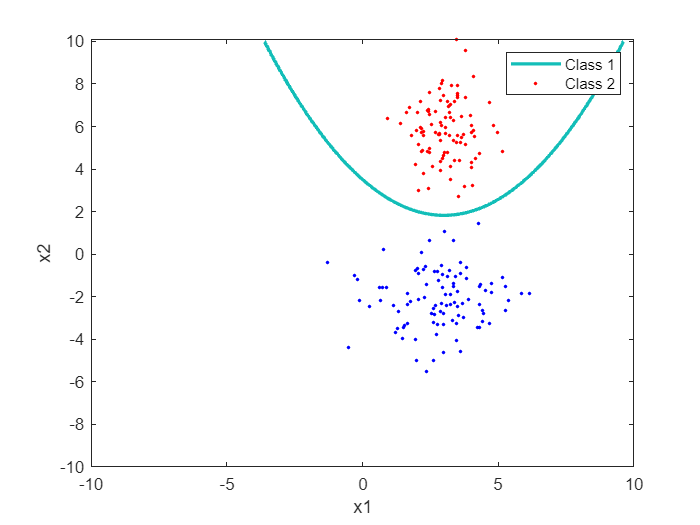

% Define the parameters
mu1 = [3; 6];
sigma1 = [0.5 0; 0 2];
mu2 = [3; -2];
sigma2 = [2 0; 0 2];

% Define the x and y range for the plot
x = -10:0.1:10;
y = -10:0.1:10;

% Calculate the decision boundary
[X, Y] = meshgrid(x, y);
Z = mvnpdf([X(:) Y(:)],mu1',sigma1) - mvnpdf([X(:) Y(:)],mu2',sigma2);
Z = reshape(Z, length(y), length(x));

% Plot the decision boundary
contour(x, y, Z, [0 0], 'LineWidth', 2);
hold on;

% Plot the data points
x1 = mvnrnd(mu1, sigma1, 100);
x2 = mvnrnd(mu2, sigma2, 100);
plot(x1(:,1), x1(:,2), 'r.');
plot(x2(:,1), x2(:,2), 'b.');
legend('Class 1', 'Class 2');

% Label the axes
xlabel('x1');
ylabel('x2');

## ***Answer: 2***

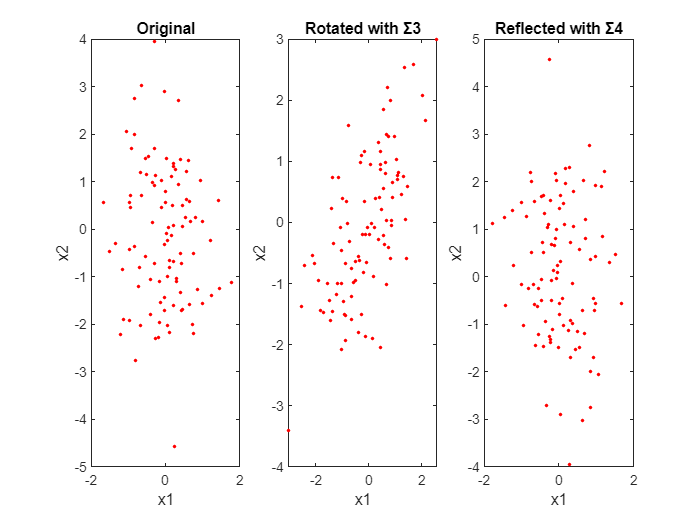

% Define the parameters
mu = [0; 0];
sigma1 = [0.5 0; 0 2];
alpha = pi/4;
sigma3 = [cos(alpha) -sin(alpha); sin(alpha) cos(alpha)];
sigma4 = [-1 0; 0 -1];

% Define the x and y range for the plot
x = -10:0.1:10;
y = -10:0.1:10;

% Generate the data points
x1 = mvnrnd(mu, sigma1, 100);
x3 = x1 * sigma3;
x4 = x1 * sigma4;

% Plot the original data points
subplot(1,3,1);
plot(x1(:,1), x1(:,2), 'r.');
title('Original');
xlabel('x1');
ylabel('x2');

% Plot the transformed data points with Σ3
subplot(1,3,2);
plot(x3(:,1), x3(:,2), 'r.');
title('Rotated with Σ3');
xlabel('x1');
ylabel('x2');

% Plot the transformed data points with Σ4
subplot(1,3,3);
plot(x4(:,1), x4(:,2), 'r.');
title('Reflected with Σ4');
xlabel('x1');
ylabel('x2');

## ***Answer: 3***

% Load the iris data
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.data';
data = urlread(url);

% Preprocess the data
C = textscan(data,'%f%f%f%f%s','Delimiter',',');
data = [C{1} C{2} C{3} C{4}];

% Define the response variable
response = double(strcmp(C{5},'Iris-setosa')) + 1;

% Fit the logistic regression model
B = mnrfit(data, response);

% Define the cases to classify
cases = [6.5 2.9 5.5 2.0; 5.0 3.4 1.5 0.2; 5.9 2.7 4.3 1.3];

% Use the logistic regression model to classify the cases
prob = mnrval(B, cases);
classes = double(prob(:,2) > 0.5) + 1;

% Print the results
disp('Classification Results:');

Classification Results:


disp(classes);

     1
     2
     1



## ***Answer: 4***

% Load the data3.xlsx file
data = xlsread(['D:\TUNI\Courses\Period-4\DATA.ML.210 [Machine Learning Algorithms]' ...
    '\Exercises 4\data3.xlsx']);

% Split the data into features (X) and response variable (y)
X = data(:,1:2);
y = data(:,2);

% Center the data
X = X - mean(X);

% Find the direction w that maximizes the margin
[u,s,v] = svd(X' * X);
w = v(:,1);

% Project the data onto w
z = X * w;

% Calculate the margin
C1 = z(y == 1);
C2 = z(y == -1);
margin = (max(C1) - min(C2)) / norm(w);

% Print the length of the separating margin
fprintf('Length of the separating margin: %f\n', margin);

Length of the separating margin: 


## ***Answer: 5***

% Load the Iris data set
load fisheriris

% Split the data into features (X) and response variable (y)
X = [meas(1:40,:); meas(51:90,:)];
y = [species(1:40); species(51:90)];

% Fit a SVM to the data
svmModel = fitcsvm(X, y, 'ClassNames', {'setosa', 'versicolor'});

% Predict the classes of the remaining ten setosa and versicolor cases
Xnew = [meas(41:50,:); meas(91:100,:)];
labels = predict(svmModel, Xnew);

% Print the predicted classes
disp(labels)

    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}



## ***Answer: 6***

% Load the Iris data set
load fisheriris

% Split the data into features (X) and response variable (y)
X = [meas(1:40,:); meas(51:90,:); meas(101:140,:)];
y = [species(1:40); species(51:90); species(101:140)];

% Fit a multi-class SVM to the data
svmModel = fitcecoc(X, y);

% Predict the classes of the remaining ten setosa, versicolor, and virginica cases
Xnew = [meas(41:50,:); meas(91:100,:); meas(141:150,:)];
labels = predict(svmModel, Xnew);

% Print the predicted classes
disp(labels)

    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'setosa'    }
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'versicolor'}
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }
    {'virginica' }

